ejemplo 1:

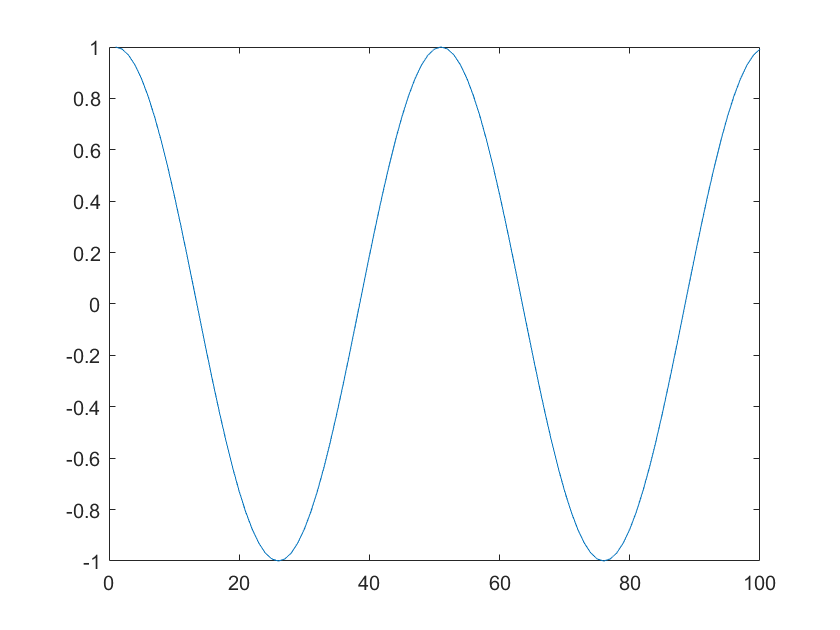

% Deterministic Discrete Sinusoidal Wave with Vpp=2 and offset=0
n = 0:1e3;  A=1; f0=1/50; wo= 2*pi*f0;
xn = A*cos(wo*n); % Original signal, a sine wave

plot(xn(1:100))

mean(xn)

ans = 9.9900e-04

var(xn)

ans = 0.5010


RMS = sqrt(var(xn))

RMS = 0.7078

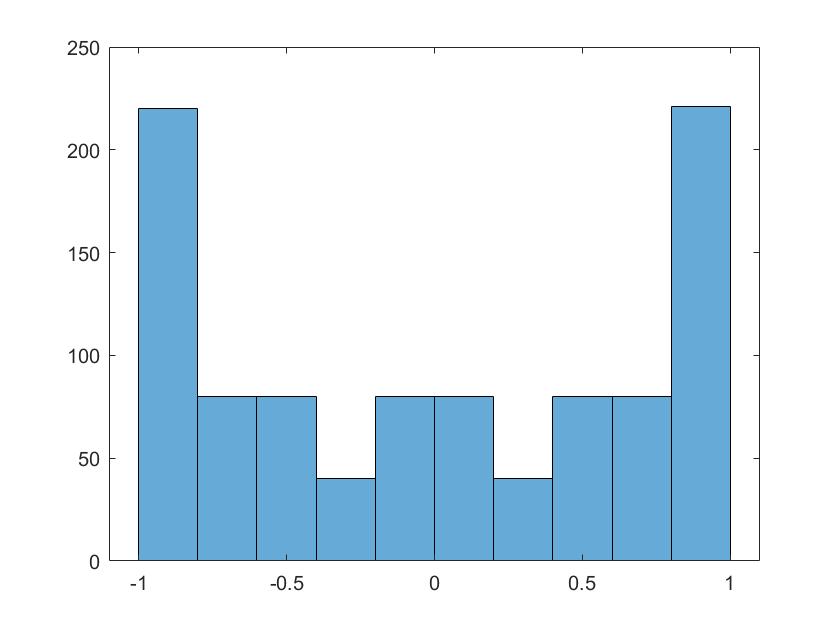

histogram(xn,10)

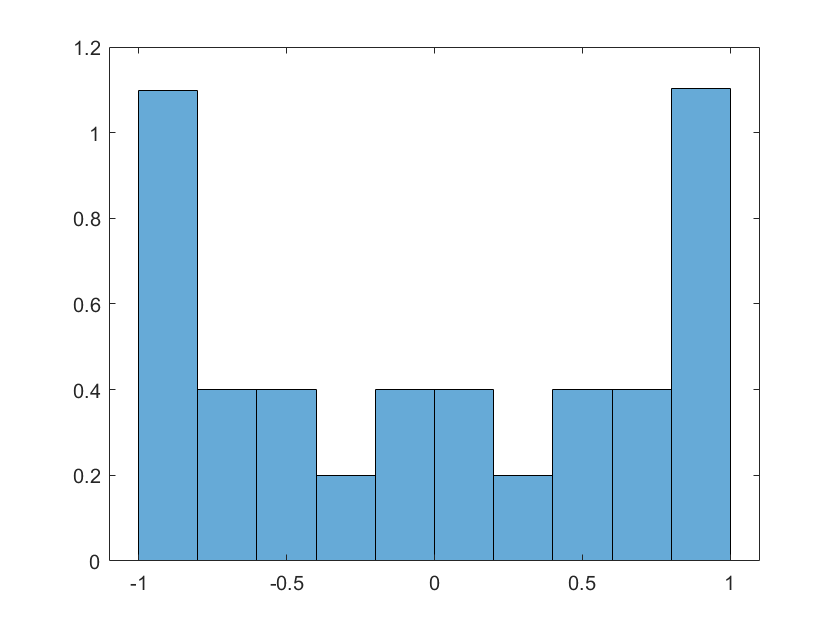

histogram(xn,'Normalization','pdf'); 

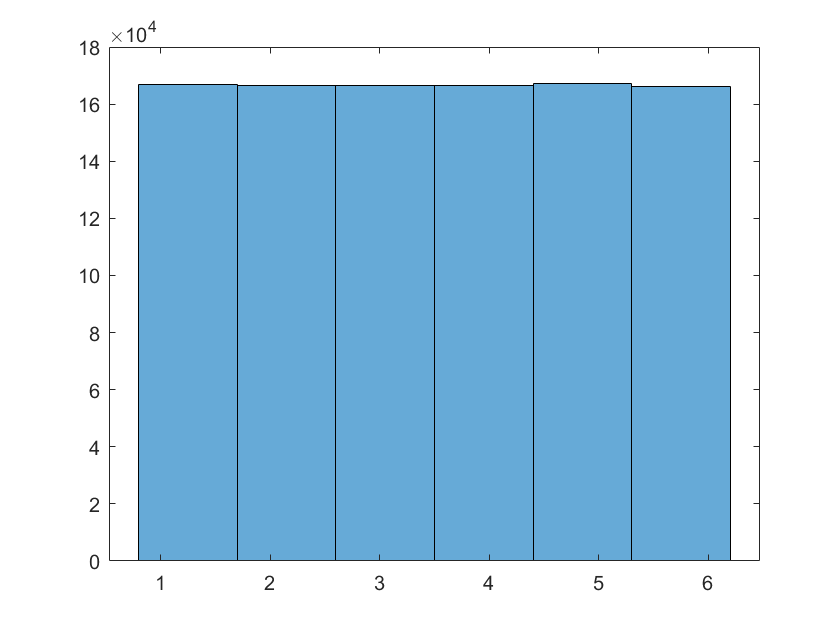


% Discrete Random variable (RV) with uniform Probability Mass Function (PMF)
xD=randi([1 6], 1,1e6);
histogram(xD,6)

mean(xD)

ans = 3.4992

var(xD)

ans = 2.9166


potencia = sum(xD.^2/numel(xD))

potencia = 15.1610

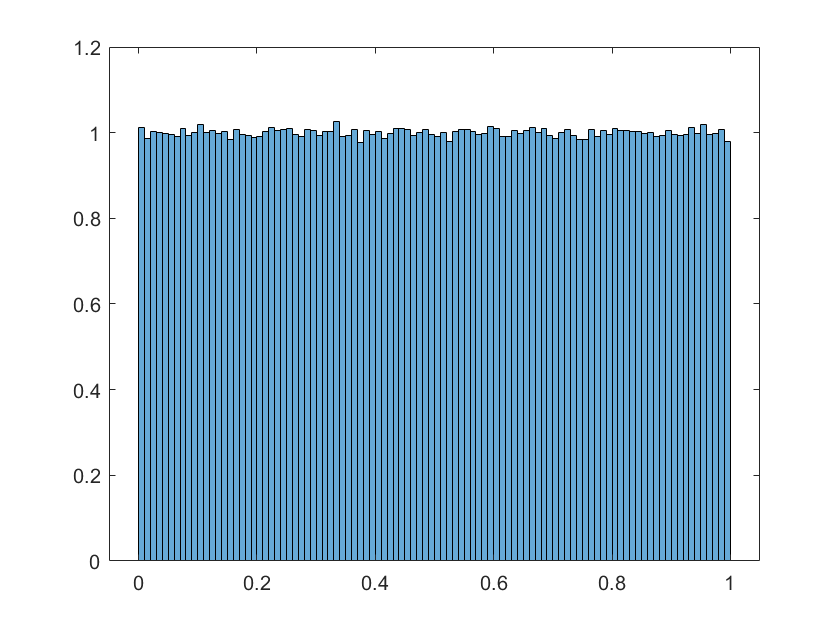


% Continuous RV with uniform Probability Density Function (PDF)
xU=rand(1,1e6);
histogram(xU,'Normalization','pdf'); % plots an estimate of the PDF for X

mean(xU)

ans = 0.4999

var(xU)

ans = 0.0833

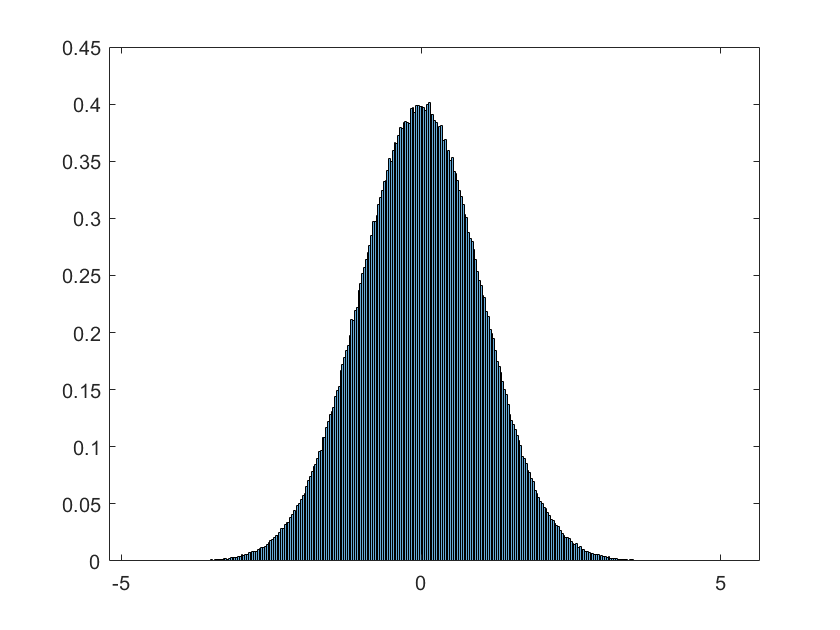

% Continuous RV with Gaussian Probability Density Function (PDF)
xG=randn(1,1e6);
histogram(xG,'Normalization','pdf'); 

mean(xG)

ans = -0.0017

var(xG)

ans = 0.9989

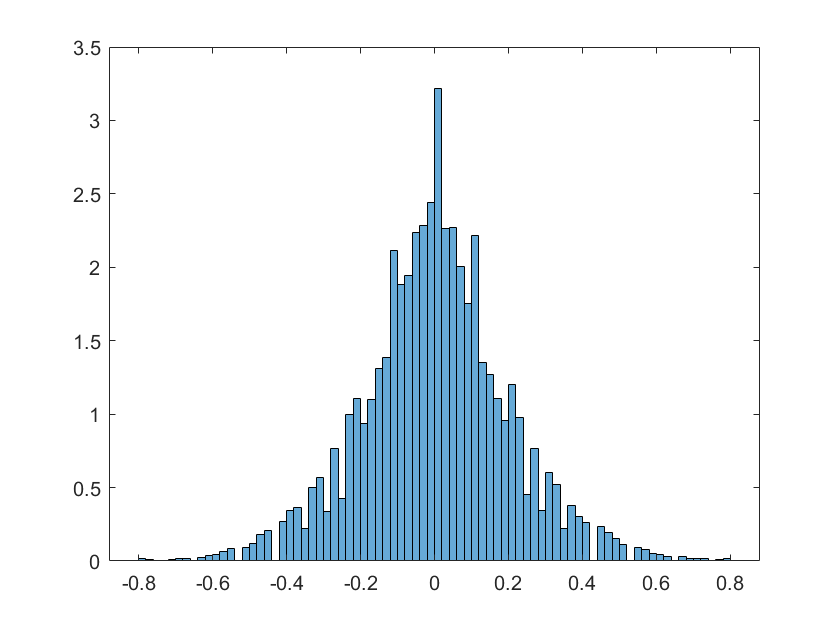

%Audio Signal
load handel.mat
histogram(y,'Normalization','pdf'); 